# Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [<https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)>

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo.  [<http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)>

clear all; close all; clc
% % run ../../install.m
% % change to example directory
% exampleDir = fileparts(mfilename('fullpath'));
% cd(exampleDir)

**system parameters**

nDiscretization = 10; % (#DOFs is proportional to the square of this number)
epsilon = 0.3;

## generate model

Building FE model


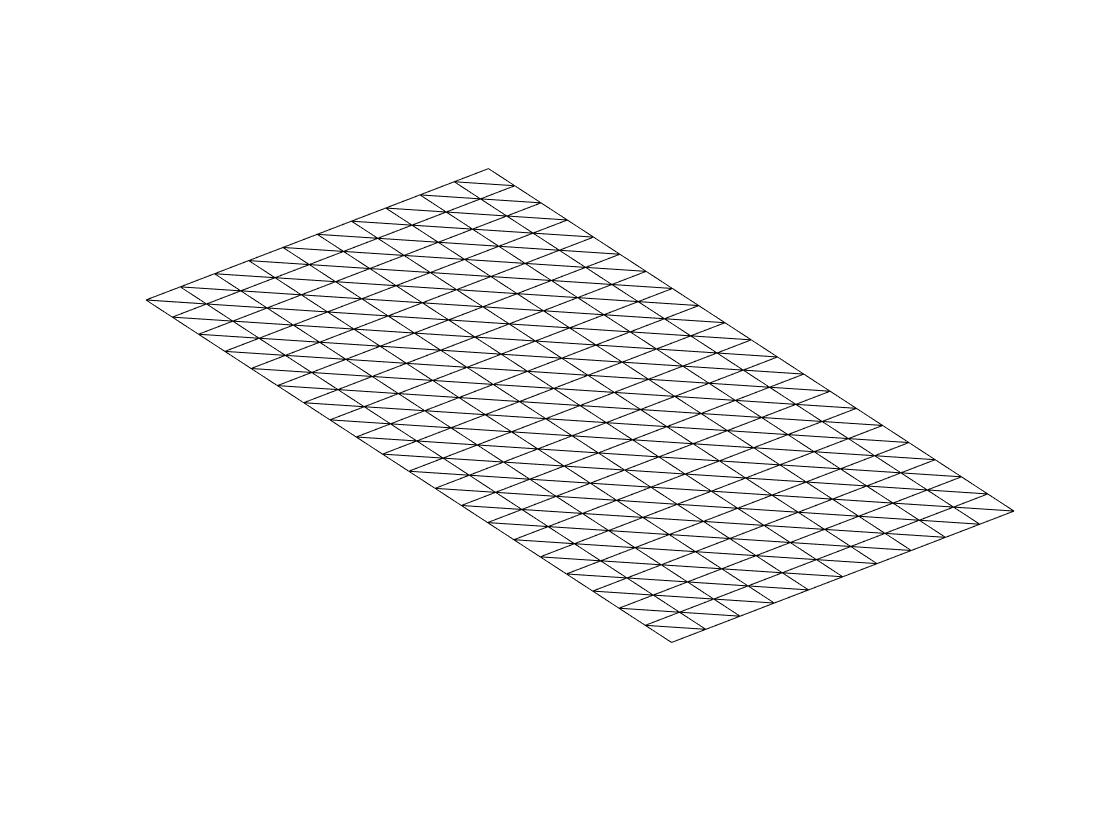

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


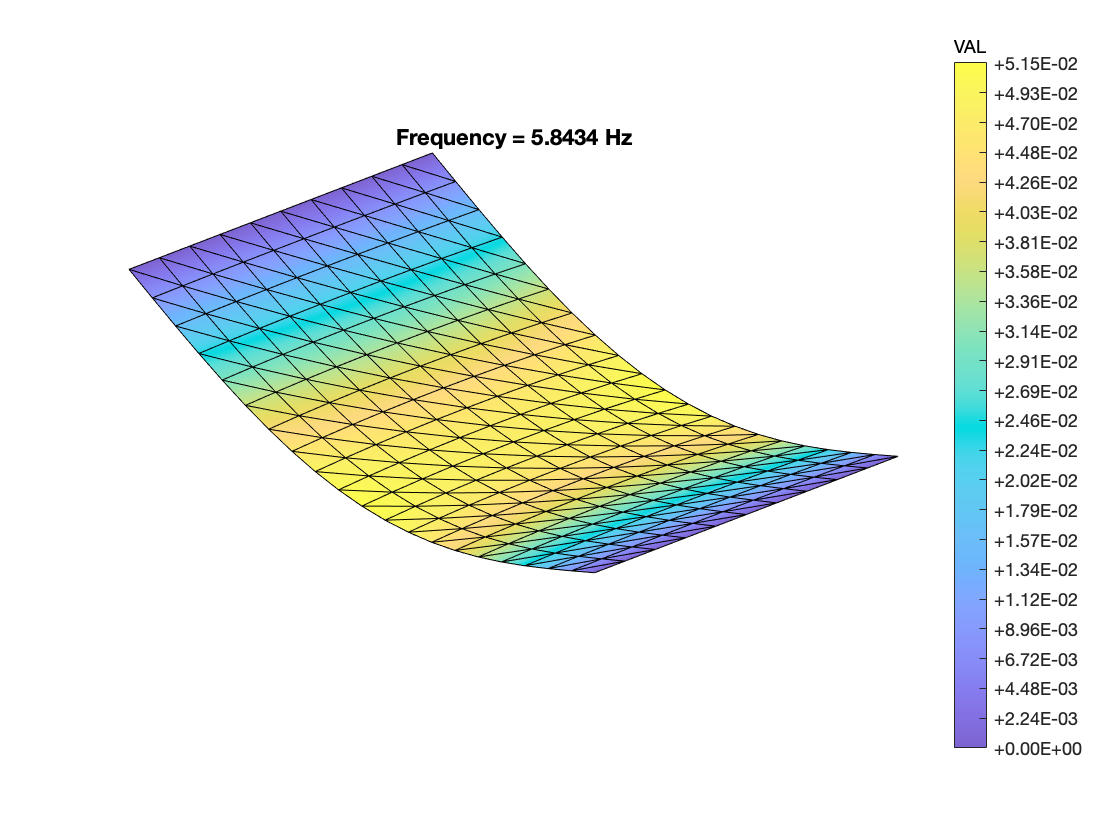

Using Rayleigh damping
Getting nonlinearity coefficients
Loaded tensors from storage
Assembling external force vector


[M,C,K,fnl,outdof,out] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


Build stochastic forcing

[filterPSD] = build_stochasticF(outdof,n,epsilon);

## Dynamical system setup 

We consider the finite element model is under vertical random uniform body force,


$$\mathbf{M \ddot{x}}+\mathbf{C \dot{x}}+\mathbf{K x}+\mathbf{F}_{nl}(\mathbf{x},\mathbf{\dot{x}})=\mathbf{Gf}$$


The model with n degree-of-freedom is forced by the uniform body force.

The body force vector $\mathbf{G}$ denotes the forcing degree-of-freedom on each element and the random forcing $\mathbf{f}$ follows the output from a second order system:

                                            
$$H(s) = \frac{s}{ms^2+ cs+k}$$


and $\Phi_{\mathbf{f}} = H(j \omega) I$

where $I$ is the intensity of Gaussian white noise.

We take the output of the second order system under white noise excitation.

setting for the SDE solver and allocate desired output PSD pairs

SS = StochasticSystem();   
set(SS,'filterPSD',filterPSD,'linear',false,'inputForcingType','vel')
set(SS,'M',M,'C',C,'K',K,'fnl',fnl);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
set(SS.SSOptions,'ssMethod','indirect','tol',1e-12)
nRealization = 24;
T0 = 30; %% PSD frequency domain resolution is ~ 1/T0
nPoints = 2^17; %% control the accuracy of numerical differential equation

We set the method of solving SDE and the output PSD.

%%%%%%%% Above is forcing setting and set to DynamicalSystem class
method = "filter ImplicitMidPoint";
PSDpair = [out,out];

SS.add_random_forcing(nRealization, T0, nPoints,outdof);
freq_range = [30 55];

## Linear Modal analysis and SDE

[V,D,W] = SS.linear_spectral_analysis();
firts_res = abs(imag(D(1)));
tic
[w,outputPSD] = SS.monte_carlo_average(method,PSDpair,nRealization);
time_sde = toc;
disp(['Total number of ',num2str(nRealization),'# realization takes ',...
    num2str(time_sde),' amount of time'])
% *Linear Analytic*
[w_linear,linear_analytic] = SS.compute_linear_PSD(PSDpair,freq_range);

## SSM set up

**Choose Master subspace (perform resonance analysis)**

S = SSM(SS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
set(S.PSDOptions, 'nPointfilter', 1)
masterModes = [1,2];
S.choose_E(masterModes);
order = 5; % Approximation order

## Compute PSD from SSM

S.ssmSEulerTimeDisp = false;
tic
[wss,ssmPSD] = S.extract_PSD(PSDpair, order,'filter heun',freq_range);
time_ssm = toc;
disp([num2str(time_ssm),' amount of time'])

## Plot

clear omega
clear Gxx
omega.w = w; Gxx.Gfull = outputPSD;%outputPSD;
omega.linear = w_linear; Gxx.linear_analytic = linear_analytic;
omega.wss = wss; Gxx.Gss = ssmPSD;
omega.w_full_linear = w_galerkin; Gxx.full_linear = PSD_galerkin;
plot_log_PSD(omega,Gxx,order,PSDpair,[20 50],true)